# Object detector

Object detection is an easy or difficult task depending on the type of object to be recognized. It is easy to detect objects of a certain color in an image through an RGB camera or it can be a more complex task like identifying a human face in a group.

In this lesson We will show you how to use a simple object detection in simulated fashion.

#### Define an ObjectDetector object and set parameters such as: 

- Field of view.

- Maximum range ( distance from the robot to detect objects).

- Maximum detection.

detector = ObjectDetector;
detector.fieldOfView = pi/2; % Field of View [rad]
detector.maxRange = 1; % Max range distance [m]        
detector.maxDetections = 5; % Max number of detections

Create a visualizer2D and attach detector.

viz = Visualizer2D;
attachObjectDetector(viz,detector);

Load an image as map and assign to visualizer.

map = generateMap(which('world1.png'), 0.1, 10);

viz.mapName = 'map';

Objects are defined  to be detected as follows:

 object_coordinates= [ 1.0 1.0;         %Matrix in coordinates
                       1.5 1.5;
                       2.0 2.0];

If you want to choose object coordinates by Clicking on the field, comment de aboveline and uncomment the following:

%show(map);
%[x,y] = getpts();
%object_coordinates = [x,y];

Note:  To finish  right click  and close emergent window.

[n, ~] = size(object_coordinates);
colors = zeros(n,3);  %Matrix to store each color marker
objects = zeros(n,3); %Matrix to store cordinates and  a numeric id
markers=''; %String where you defins the shape by a Char 

If you want to know all the markesr check [this link](https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html).


for i=1:n
    %Set x,y and id for each object
    objects(i,1) = object_coordinates(i,1);
    objects(i,2) = object_coordinates(i,2);
    objects(i,3) = i;
    %Set color for each object
    colors(i,1) = .3;
    colors(i,2) = .8;
    colors(i,3) = .5;
    %Set marker for each object
    markers = strcat(markers,'s');
end

Note: The above definitions related to objects will be replace in next lessons by objectsByCoordinates or objectsByClick  function:

%[objects,colors,markers] = objectsByCoordinates(object_coordinates);
% or
%[objects,colors,markers] = objectsByClick(map);

Set Colors and markers  to visualizer.

viz.objectColors = colors;
viz.objectMarkers = markers;

Define initial pose and  differential  robot.

initPose = [ 1; 1.5; 0]; % [x ; y ; theta]    
R = 0.3; 
L = .12; 
robotRadius = .075;
mobileRobot = DifferentialDrive(R,L);

viz.robotRadius = robotRadius;

Velocity definition.

v = .1; % [m/s]
w = 0.5; % [rad/s]
bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in its 'y' axis.

### Execute simulation

currentPose = initPose;
[sampleTime,tVec,r] = simulTime(0.1,10); % Define Sample time, time array and rate control 
for idx = 2:numel(tVec) 
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
   

 Detections at time $t$ is  store in detection matrix computed by detector (inputs: pose and object on the field).

It returns a matrix where each row contains  $\left\lbrack d\;\;\theta \;\;\textrm{id}\right\rbrack$  distance and angle from robot to object and id.

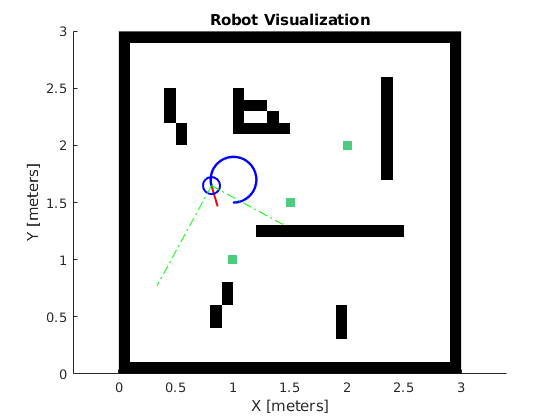

    detections = detector(currentPose,objects) ;
    
    % Update visualization
    viz(currentPose,objects);
    
    %Wait for visualization rate
    waitfor(r);
    
end

# Practice

Create a matlab Script(.m) to visualize the simulation and at the same time show the objects detected information in console.

Change objects position, markers and color for each one.